clc;
clear;

%DATA LOADED TO MATLAB
%https://www.kaggle.com/code/davegn/rice-type-classification
Table = 'C:\Users\dimin\OneDrive - City, University of London\Desktop\RiceClassification.csv';
opts = detectImportOptions(Table);
opts.VariableNamingRule = 'preserve';
data = readtable('C:\Users\dimin\OneDrive - City, University of London\Desktop\RiceClassification.csv', opts)

data = 18185×12 table
    id    Area    MajorAxisLength    MinorAxisLength    Eccentricity    ConvexArea    EquivDiameter    Extent     Perimeter    Roundness    AspectRation    Class
    __    ____    _______________    _______________    ____________    __________    _____________    _______    _________    _________    ____________    _____

     1    4537        92.229             64.013           0.71992          4677          76.005        0.65754     273.08       0.76451        1.4408         1  
     2    2872        74.692               51.4           0.72555          3015    

originalHeaders = data.Properties.VariableDescriptions;

%EXPLORATORY DATA ANALYSIS
data.id = [];%Removing the identification column as it is not needed
summary(data);%Printing a statistics summary for the dataset

Variables:

    Area: 18185×1 double

        Values:

            Min         2522  
            Median      6660  
            Max        10210  

    MajorAxisLength: 18185×1 double

        Values:

            Min        74.133 
            Median     153.88 
            Max        183.21 

    MinorAxisLength: 18185×1 double

        Values:

            Min         34.41 
            Median     55.724 
            Max        82.551 

    Eccentricity: 18185×1 double

        Values:

            Min       0.67665 
            Median    0.92326 
            Max       0.96677 

    ConvexArea: 18185×1 double

        Values:

            Min         2579  
            Median      6843  
            Max        11008  

    EquivDiameter: 18185×1 double

        Values:

            Min        56.667 
            Median     92.086 
            Max        114.02 

    Extent<

%Pie chart which shows the percentage of each class type in the dataset.
%This was created to understand how balanced the target variable is.
class(data.Class);%Checking the data type of the Class column in the dataset
if ~iscategorical(data.Class)
    data.Class = categorical(data.Class)
end%Checking if the Class data type is categorical and if not converting it to.

data = 18185×11 table
    Area    MajorAxisLength    MinorAxisLength    Eccentricity    ConvexArea    EquivDiameter    Extent     Perimeter    Roundness    AspectRation    Class
    ____    _______________    _______________    ____________    __________    _____________    _______    _________    _________    ____________    _____

    4537        92.229             64.013           0.71992          4677          76.005        0.65754     273.08       0.76451        1.4408         1  
    2872        74.692               51.4           0.72555          3015          60.471        0.71301     208.32       0.83166      

counts = countcats(data.Class);%Counting the number of each classification
categories = categories(data.Class);%Obtaining the unique categories in the Class column

pie(counts);%Creating a pie chart using the counts of each class
legendLabels = {'Gonen', 'Jasmine'}

legendLabels = 1×2 cell array
    {'Gonen'}    {'Jasmine'}


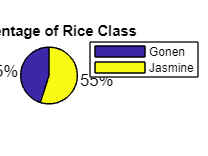

legend(legendLabels, 'Location', 'bestoutside');
title('Percentage of Rice Class');

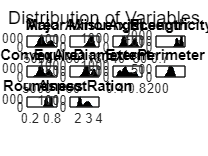

%Histograms showing the distribution of the X variables of the dataset
%This was created in order to understand the distributions of the variables
%in the dataset.
dataWithoutClass = removevars(data, 'Class');%Removing the Class column from the dataset, by creating a new one where Class is absent

numericVars = varfun(@isnumeric, dataWithoutClass, 'OutputFormat', 'uniform');%Identifying the numerical variables in the dataset and making sure that the result is a single array
numericData = dataWithoutClass(:, numericVars);%Making sure that only columns with numerical variables are present

numNumericVars = sum(numericVars);%Counting the number of numerical variables present 
%Determining the number of rows and columns to calculate the size of the
%subplot
numRows = ceil(sqrt(numNumericVars));
numCols = numRows; 

figure;%Creating the subplot
for i = 1:numNumericVars
    subplot(numRows, numCols, i);
    histogram(dataWithoutClass{:, i}); 
    title(dataWithoutClass.Properties.VariableNames{i});
end
sgtitle('Distribution of Variables');

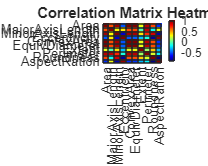

%Correlation Matrix  Heatmap computation
%This was computed in order to observe the relationships between the
%variables of the dataset.
numericArray = table2array(numericData);%Converting the numerical table to a numerical array
corrMatrix = corr(numericArray, 'Rows', 'complete');%Computation of the correlation matrix excluding any rows with missing values
figure('Position', [100, 100, 1000, 800]);%Stating the dimensions of the heatmap
heatmap(numericData.Properties.VariableNames, numericData.Properties.VariableNames, corrMatrix, 'Colormap', jet, 'Title', 'Correlation Matrix Heatmap');%Specifying colour, title etc..

%DATA PRE-PROCESSING
% Min-Max Normalization
numericData = data(:, varfun(@isnumeric, data, 'OutputFormat', 'uniform')); %Extracting numeric values from the dataset
minVals = min(table2array(numericData), [], 1);%Calculating the minimum values
maxVals = max(table2array(numericData), [], 1);%Calculating the maximum values
normData = (table2array(numericData) - minVals) ./ (maxVals - minVals);%Applying the normalization
data{:, varfun(@isnumeric, data, 'OutputFormat', 'uniform')} = normData;%Placing the normalized values back to the dataset

%Data Transformations: Applying the Box-Cox Transformation
%This was done in order to change the distributions of some variables so
%that they are closer to normal distributions, even though MLP is generally
%robust to non-normal data.
variables = data.Properties.VariableNames;%Obtaining all the variable names from the dataset
lambdas = struct();%Creating a structure to store the lamba values obtained

for var = variables%Iterating over each variable in the dataset
    if strcmp(var, 'Class') || ~isnumeric(data.(var{1}))%If the variable is Class or non-numeric it is skipped.
        continue;
    end
    minValue = min(data.(var{1}));%Finding the minimum value of the variable that is checked at that moment
    adjustment = 0;%Initializing adjustment factor to 0
    if minValue <= 0%If the minimum value is less or equal to 0, it is made positive since the Box-Cox transformation only works with positive values
        adjustment = abs(minValue) + 1; 
        adjustedData = data.(var{1}) + adjustment;
    else
        adjustedData = data.(var{1});
    end
    
    [transformed, lambda] = boxcox(adjustedData);%Applying the transformation
    data.(var{1}) = transformed;%Updating the original dataset with the transformed data
    lambdas.(var{1}) = lambda;%Storing the lamba values
end

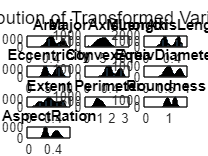

%This subplot contains histograms of the transformed variables. Comparing
%to the previous subplot, it can be observed that the variables now are
%closer to normality.
variables = data.Properties.VariableNames;

numericVars = variables(~strcmp(variables, 'Class')); 
numNumericVars = numel(numericVars); 

numRows = ceil(sqrt(numNumericVars)); 
numCols = ceil(numNumericVars / numRows); 

figure;
subplotIndex = 1;

for var = numericVars
    if isnumeric(data.(var{1}))
        subplot(numRows, numCols, subplotIndex);
        histogram(data.(var{1})); 
        title(var{1}); 
        subplotIndex = subplotIndex + 1; 
    end
end
sgtitle('Distribution of Transformed Variables');

%NEURAL NETWORK CONSTRUCTION AND DATA PARTITIONING
X = data{:, {'Area', 'AspectRation', 'ConvexArea', 'Eccentricity', 'EquivDiameter', 'Extent', 'MajorAxisLength', 'MinorAxisLength', 'Perimeter', 'Roundness'}};
%Selecting the specific features from the dataset
Y = data.Class;%Selecting the target variable
cv = cvpartition(size(X, 1), 'HoldOut', 0.3); %Data is splitted to 70% training and 30% testing data
idx = cv.test;%Creating an index vector
%Splitting the features into datasets according to the index vector
X_train = X(~idx, :);
Y_train = Y(~idx, :);
X_test = X(idx, :);
Y_test = Y(idx, :);

%Convert categorical variables to numerical
%This was done because neural networks require numerical inputs. The
%dummyvar function is used to convert the categorical variable into a set of dummy/indicator variables.
Y_train = dummyvar(categorical(Y_train));
Y_test = dummyvar(categorical(Y_test));

%Hyperparameters to iterate over
learning_rates = [0.01, 0.1, 0.3];%Defining a set for the learning rate
hidden_sizes = [10, 20, 30];%Defining a size for the hidden layers
epochs = 1;%Defining the number of epochs

%Performance of evaluations and predictions for different hyperparameters
rng(28);%Random seed for reproducability
results = [];%Initializing an empty array to store the results

for lr = learning_rates%Iterate over each learning rate
    for hs = hidden_sizes%Iterate over each hidden layer
        %Neural network setup
        net = patternnet(hs);%Creating the network with the specified hidden layer size
        net.trainParam.lr = lr;%Setting the learning rate of the network
        net.trainParam.epochs = epochs;%Setting the epochs of the network
        net.trainParam.showWindow = false;
        net.layers{1}.transferFcn = 'tansig';%Specifying the activation function 
        net.layers{end}.transferFcn = 'logsig';%Specifying the transfer function for the output layer
        %Start timer to measure training time
        tic;
        %Training the neural network
        [net, tr] = train(net, X_train', Y_train');
        %Timer stopped
        training_time = toc;
        %Testing the network
        Y_pred = net(X_test');%Testing the network on the test set
        Y_pred_round = Y_pred >= 0.50;%Setting a treshold for binary classification
        test_accuracy = sum(Y_pred_round' == Y_test) / numel(Y_test);%Calculating the test accuracy of the network
        %Setting up the results obtained to be printed
        result = struct('learning_rate', lr, 'hidden_size', hs, ...
                        'test_accuracy', test_accuracy, 'training_time', training_time);
        results = [results, result];
    end
end

for i = 1:length(results)%Displaying the results
    fprintf('Learning Rate: %.2f, Hidden Size: %d, Test Accuracy: %.4f, Training Time: %.2f seconds\n', ...
    results(i).learning_rate, results(i).hidden_size, results(i).test_accuracy, results(i).training_time);
end

Learning Rate: 0.01, Hidden Size: 10, Test Accuracy: 0.2316, Training Time: 0.27 seconds
Learning Rate: 0.06, Hidden Size: Learning Rate: 0.01, Hidden Size: 20, Test Accuracy: 0.2274, Training Time: 0.27 seconds
Learning Rate: 0.04, Hidden Size: Learning Rate: 0.01, Hidden Size: 30, Test Accuracy: 0.2353, Training Time: 0.27 seconds
Learning Rate: 0.04, Hidden Size: Learning Rate: 0.10, Hidden Size: 10, Test Accuracy: 0.2272, Training Time: 0.27 seconds
Learning Rate: 0.03, Hidden Size: Learning Rate: 0.10, Hidden Size: 20, Test Accuracy: 0.2272, Training Time: 0.27 seconds
Learning Rate: 0.04, Hidden Size: Learning Rate: 0.10, Hidden Size: 30, Test Accuracy: 0.2274, Training Time: 0.27 seconds
Learning Rate: 0.04, Hidden Size: Learning Rate: 0.30, Hidden Size: 10, Test Accuracy: 0.4078, Training Time: 0.27 seconds
Learning Rate: 0.03, Hidden Size: Learning Rate: 0.30, Hidden Size: 20, Test Accuracy: 0.4762, Training Time: 0.27 seconds
Learning Rate: 0.04, Hidden Size: Learning Rate: 0

Y_test = Y_test(:);%Reshaping the Y_test array into a vector
Y_pred_round = double(Y_pred_round(:));%Converting Y_pred_rounded into a double

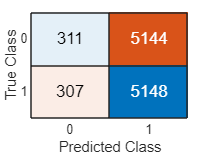

%Confusion matrix calculation, based on true labels(Y_test) and the
%predicted labels(Y_pred_rounded)
[C,order] = confusionmat(Y_test,Y_pred_round);
%Confusion matrix visualization
figure;
confusionchart(C,order);
saveas(gcf, 'confusionchart.png'); 

%Computation of performance metrics, such as Precision, Recall and F1
%score. These were computed using the elements obtained from the confusion
%matrix.
TP = C(2,2);%True positive calculation 
TN = C(1,1);%True negative calculation
FP = C(1,2);%False positive calculation
FN = C(2,1);%False negative calculation
precision = TP / (TP + FP);%Calculation of precision which is the ratio of true positives to all the predicted positives
recall = TP / (TP + FN);%Calculation of recall which is the ratio of true positives to all actual positives
F1 = 2 * (precision * recall) / (precision + recall);%F1 score calculation, which is a mean of precision and recall
fprintf('Precision: %.2f\n', precision);

Precision: 0.50


fprintf('Recall: %.2f\n', recall);

Recall: 0.94


fprintf('F1 Score: %.2f\n', F1);

F1 Score: 0.65


fprintf('True Positive: %.2f/n', TP);

True Positive: 5148.00/n

fprintf('True Negative: %.2f/n', TN);

True Negative: 311.00/n

fprintf('False Positive: %.2f/n', FP);

False Positive: 5144.00/n

fprintf('False Negative: %.2f/n', FN);

False Negative: 307.00/n

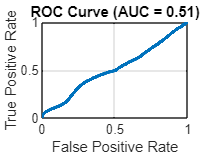

Y_pred = double(Y_pred(:));%Converting the predicted labels to double to ensure that it is a column vector
Y_test = double(Y_test(:));%Converting the actual labels to double to ensure that it is a column vector

[X_ROC, Y_ROC, T, AUC] = perfcurve(Y_test, Y_pred, 1);%Computing the RoC curve, using the false positive rate, true positive rate, the tresholds and area under the curve
figure;%Creating a figure for the curve
plot(X_ROC, Y_ROC, 'LineWidth', 2);%Plotting the curve
title(sprintf('ROC Curve (AUC = %.2f)', AUC));
xlabel('False Positive Rate');
ylabel('True Positive Rate');
grid on;
saveas(gcf, 'RoC Curve.png');